# 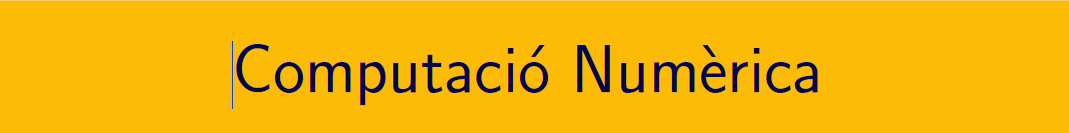

================================================================================

# Pràctica 12. Equacions diferencials ordinàries (II).

`Document preparat per M. Àngela Grau Gotés - 16 de maig de 2023`

## Estabilitat numèrica del mètode d'Euler

#### Problema de valors inicials

#### 
$$y'=-3 y\,, \quad y(0)=3\,, \quad y(25)=?$$


#### Solució analítica


syms y(t)
eqn = diff(y,t) == -3*y;
cond = y(0) == 3;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 3\,{\mathrm{e}}^{-3\,t}$$

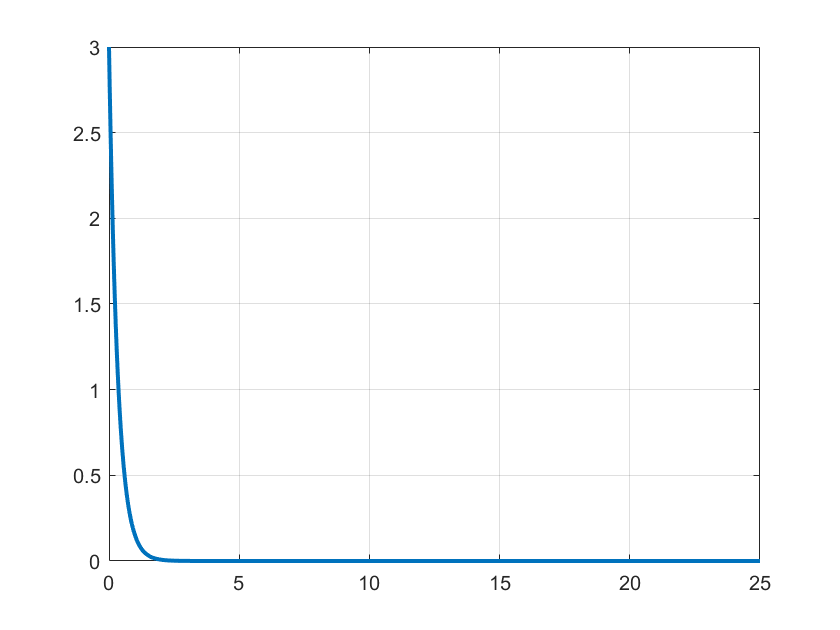

fplot(ySol,[0,25],'LineWidth',2),grid

## Método de Euler: |`ah`| <1, a=-3, 

- h=0.2 (estabilitat numèrica) 

f = @(t,y) -3*y     %y' = f(t,y) 

f = function_handle with value:
    @(t,y)-3*y


a = 0; b = 5;
alpha = 3;
h = 0.2;
[ w,t ] = Euler(f,a,b,h,alpha)

w =     3.0000    1.2000    0.4800    0.1920    0.0768    0.0307    0.0123    0.0049    0.0020    0.0008    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


t =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000


error_global = double(abs(w(end)- ySol(b)))

error_global = 9.1737e-07

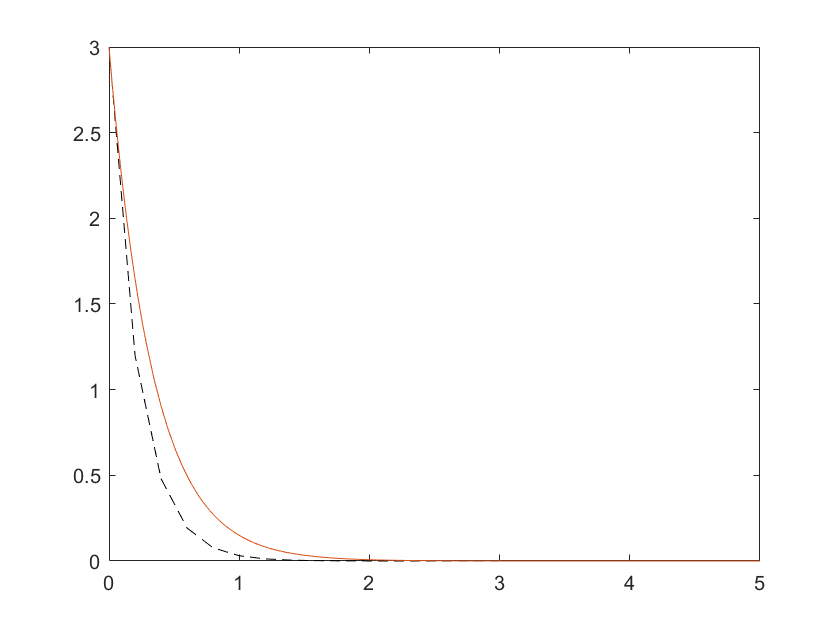


plot(t,w,'k--')
hold on
fplot(ySol, [a,b])
hold off

-  h=0.5 

f = @(t,y) -3*y     %y' = f(t,y) 

f = function_handle with value:
    @(t,y)-3*y


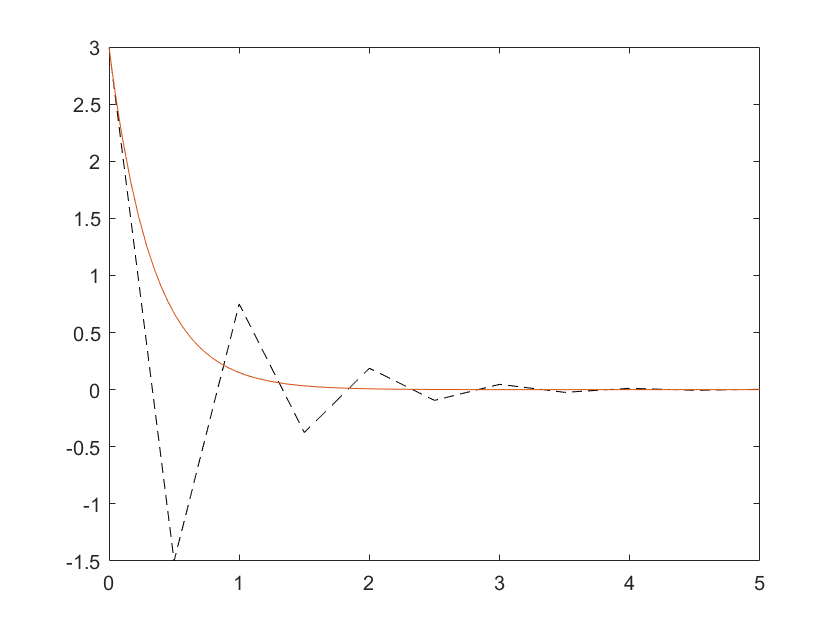

a = 0; b = 5;
alpha = 3;
h = 0.5;
[ w,t ] = Euler(f,a,b,h,alpha);
error_global = double(abs(w(end)- ySol(b)));

plot(t,w,'k--')
hold on
fplot(ySol, [a,b])
hold off

-   h=2/3 (oscila)

f = @(t,y) -3*y     %y' = f(t,y) 

f = function_handle with value:
    @(t,y)-3*y


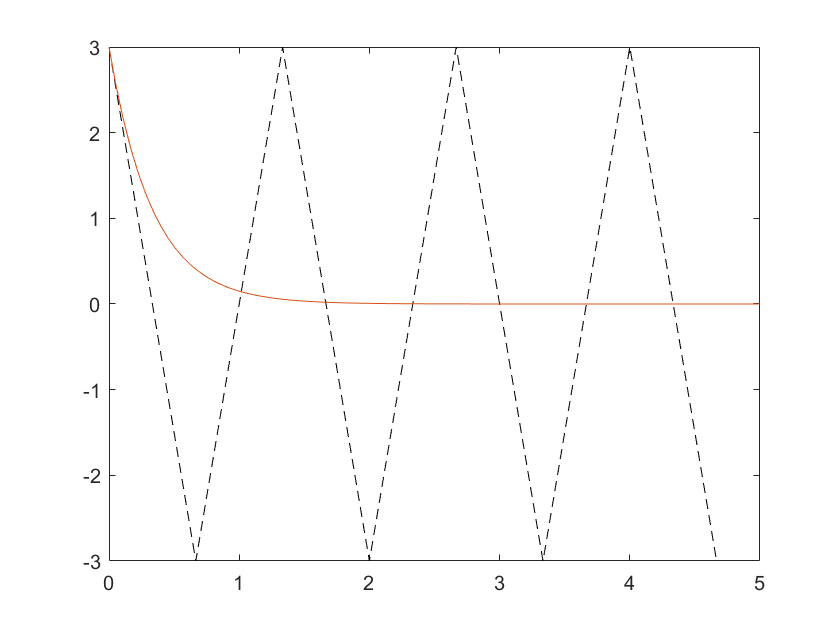

a = 0; b = 5;
alpha = 3;
h = 2/3;
[ w,t ] = Euler(f,a,b,h,alpha);
error_global = double(abs(w(end)- ySol(b)));

plot(t,w,'k--')
hold on
fplot(ySol, [a,b])
hold off

-  h=0.69 (inestable numericament)

f = @(t,y) -3*y     %y' = f(t,y) 

f = function_handle with value:
    @(t,y)-3*y


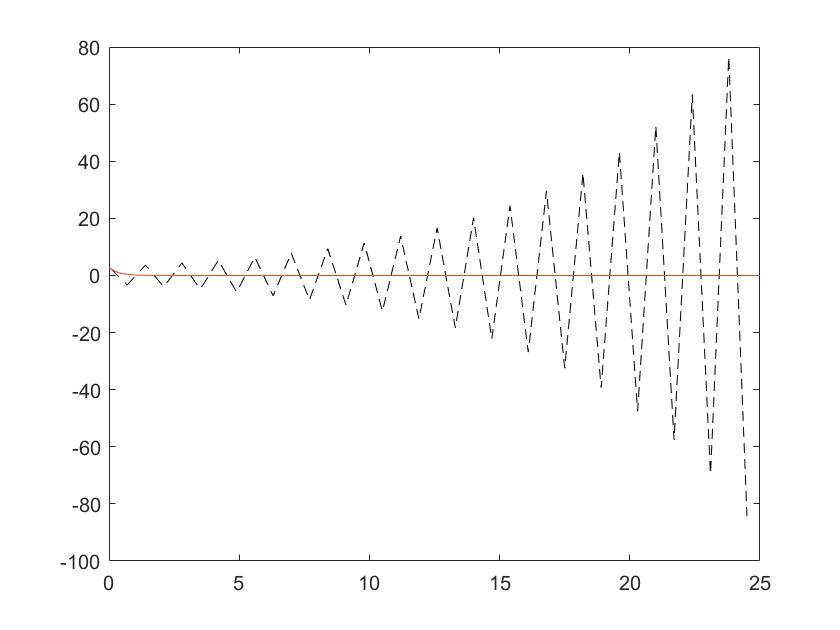

a = 0; b = 25;
alpha = 3;
h = 0.7;       % alpha*h = 2 (limit d'estabilitat)
[ w,t ] = Euler(f,a,b,h,alpha);
error_global = double(abs(w(end)- ySol(b)));

plot(t,w,'k--')
hold on
fplot(ySol, [a,b])
hold off

-  h=.....

## PRACTIQUEM... 

### Exercici. 

 Resoleu els exercicis del document practica12_edos_II.pdf disponible en el campus virtual.

## Vegeu: prac12_16maig_estabilitatEuler_practiquem.html

function [ w,t ] = Euler(f,a,b,h,alpha)
% Mètode d'Euler
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    w(i+1)=w(i)+h*f(t(i),w(i));
end
end

`Dijous 16 de maig 2023, preparat per M. Àngela Grau Gotés`